# CCLE Metabolomics and GCP ratios

**Author**: Scott Campit

## Summary

This script computes the correlation between the raw CCLE metabolomics data and ratios of histone markers.

clear all;

% Load up metabolomics
metabolomics = readtable('CCLE_metabolomics_ratios.xlsx', 'sheet', 'All')

% Load up GCP
gcp          = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'all');
[~, ia, ib]  = intersect(string(table2cell(metabolomics(:, 'CCLE_ID'))), ...
                         string(table2cell(gcp(:, 'CellLine'))));
                    
% Finally, let's get tables with matching indicies
metabolomics = metabolomics(ia, :);
gcp          = gcp(ib, :);

% Get GCP ratios
gcp_ratios = ["H3K4 ac/me1", "H3K4 ac/me2", ...
              "H3K9 ac/me1", "H3K9 ac/me2", "H3K9 ac/me3", ...
              "H3K27 ac/me1", "H3K27 ac/me2", "H3K27 ac/me3"];

% Get CCL names
cellLines = table2array(gcp(:, 'CellLine'))

## Methylation and acetylation subsets

In general, H3K4, H3K36, and H3K79 methylations are generally considered to indicate active transcription, while H3K9 and H3K27 indicate repression. Thus, meaningful ratios of histone markers include:

- H3K4me3 and H3K27me3: [https://ashpublications.org/blood/article/114/22/1046/110138/Modulation-of-Histone-H3K4-and-H3K27-Methylation](https://ashpublications.org/blood/article/114/22/1046/110138/Modulation-of-Histone-H3K4-and-H3K27-Methylation)

- H3K4me3 and H3K9me3

- H3K36me3 and H3K9me3

- H3K36me3 and H3K27me3

- H3K79me2 and H3K9me3

- H3K79me2 and H3K27me2

- All Ac/ All Me

% Acetylation markers
acetylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'acetylation');
acetylation_gcp = acetylation_gcp(ib, :);
data = rescale(table2array(acetylation_gcp(:, 2:end)));
acetylation_gcp(:, 2:end) = array2table(data);

% Methylation markers
methylation_gcp = readtable('GCP_proteomics_remapped.xlsx', 'sheet', 'methylation');
methylation_gcp = methylation_gcp(ib, :);
data = rescale(table2array(methylation_gcp(:, 2:end)));
methylation_gcp(:, 2:end) = array2table(data);

### Get GCP Ratios

h3k4_ac_me  = table2array(acetylation_gcp(:, 'H3K4ac1')) ./ ...
              table2array(methylation_gcp(:, ["H3K4me1", "H3K4me2"]))
h3k9_ac_me  = table2array(acetylation_gcp(:, 'H3K9ac1')) ./ ...
              table2array(methylation_gcp(:, ["H3K9me1", "H3K9me2", "H3K9me3"]))
h3k27_ac_me = table2array(acetylation_gcp(:, 'H3K27ac1')) ./ ...
              table2array(methylation_gcp(:, ["H3K27me1", "H3K27me2", "H3K27me3"]))
ACME = [h3k4_ac_me, h3k9_ac_me, h3k27_ac_me]
ACME(isnan(ACME)) = 0;
ACME(ACME==inf) = max(ACME(isfinite(ACME)));          

### Get Metabolomics Ratio

% Methylation

methylation_metabolomics = 927×12 table
      CCLE_ID       G3P_AKG    FUM_AKG    SUCC_AKG    GLY_AKG    SER_AKG    MET_AKG    THR_AKG    DMG_AKG    SAH_AKG    BET_AKG    CHO_AKG
    ____________    _______    _______    ________    _______    _______    _______    _______    _______    _______    _______    _______

    {'DMS53'   }     1.0067    0.98979     1.0281      1.1269     0.9231     1.1267     1.1587     1.0369      1.014     1.1396     1.1921
    {'SW1116'  }    0.87865    0.99222     1.0254      1.1531     1.1802     1.1423     1.2008    0.99674     0.9757     1.0239    0.9

methylation_metabolomics = readtable('CCLE_metabolomics_ratios.xlsx', 'sheet', 'Methylation')

methylation_metabolomics = 860×12 table
      CCLE_ID      G3P_AKG    FUM_AKG    SUCC_AKG    GLY_AKG    SER_AKG    MET_AKG    THR_AKG    DMG_AKG    SAH_AKG    BET_AKG    CHO_AKG
    ___________    _______    _______    ________    _______    _______    _______    _______    _______    _______    _______    _______

    {'22RV1'  }    0.92258     1.0087     1.0145      1.0544     1.0316     1.0184     1.0079     1.0327    0.97266     1.0528     1.0376
    {'2313287'}     1.0106    0.98516     0.9275     0.99102    0.84887     1.0263     0.9785     0.9942     1.0669    0.98438    0.95814

methylation_metabolomics = methylation_metabolomics(ia, :)

% Acetylation

acetylation_metabolomics = 927×40 table
      CCLE_ID       CIT_NAD    VAL_NAD    LEU_NAD    ISO_NAD    ALA_NAD    AC_NAD     C46_2_TAG_NAD    C46_1_TAG_NAD    C46_0_TAG_NAD    C48_3_TAG_NAD    C48_2_TAG_NAD    C48_1_TAG_NAD    C48_0_TAG_NAD    C50_3_TAG_NAD    C50_2_TAG_NAD    C50_1_TAG_NAD    C50_0_TAG_NAD    C52_5_TAG_NAD    C52_4_TAG_NAD    C52_3_TAG_NAD    C52_2_TAG_NAD    C52_1_TAG_NAD    C54_7_TAG_NAD    C54_6_TAG_NAD    C54_5_TAG_NAD    C54_4_TAG_NAD    C54_3_TAG_NAD    C54_2_TAG_NAD    

acetylation_metabolomics = readtable('CCLE_metabolomics_ratios.xlsx', 'sheet', 'Acetylation')

acetylation_metabolomics = 860×40 table
      CCLE_ID      CIT_NAD    VAL_NAD    LEU_NAD    ISO_NAD    ALA_NAD    AC_NAD     C46_2_TAG_NAD    C46_1_TAG_NAD    C46_0_TAG_NAD    C48_3_TAG_NAD    C48_2_TAG_NAD    C48_1_TAG_NAD    C48_0_TAG_NAD    C50_3_TAG_NAD    C50_2_TAG_NAD    C50_1_TAG_NAD    C50_0_TAG_NAD    C52_5_TAG_NAD    C52_4_TAG_NAD    C52_3_TAG_NAD    C52_2_TAG_NAD    C52_1_TAG_NAD    C54_7_TAG_NAD    C54_6_TAG_NAD    C54_5_TAG_NAD    C54_4_TAG_NAD    C54_3_TAG_NAD    C54_2_TAG_NAD    

acetylation_metabolomics = acetylation_metabolomics(ia, :)

### Compute ratios between acetylation and methylation marks

#### Acetylation

[acetylation_corr, acetylation_pval] = corr(ACME, table2array(acetylation_metabolomics(:, 2:end)));
mask = acetylation_corr;
mask(acetylation_pval > 0.05) = NaN;

Finally, we'll plot the data as a heatmap

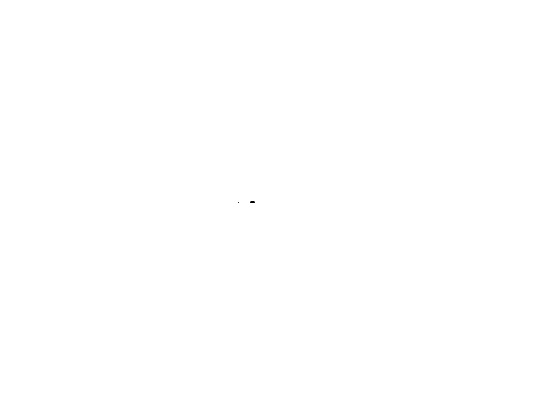

redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
ac_metabolites = strrep(acetylation_metabolomics.Properties.VariableNames(2:end), '_', ' ');
heatmap(mask', ...
        'colormap', redbluecmap, ...
        'YData', ac_metabolites, ...
        'XData', gcp_ratios, ...
        'FontSize', 45)

#### Methylation

[methylation_corr, methylation_pval] = corr(ACME, table2array(methylation_metabolomics(:, 2:end)));
mask = methylation_corr;
mask(methylation_pval > 0.05) = NaN;

Finally, we'll plot the data as a heatmap

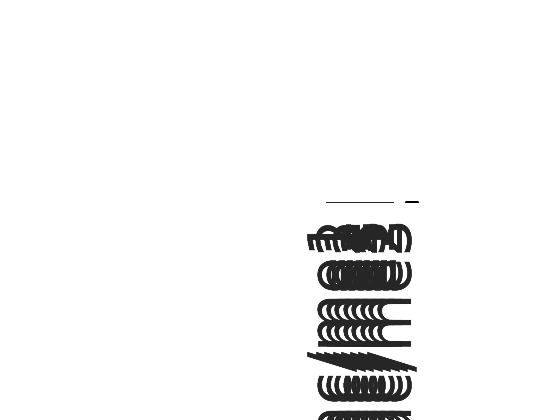

redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
me_metabolites = strrep(methylation_metabolomics.Properties.VariableNames(2:end), '_', ' ');
heatmap(mask', ...
        'colormap', redbluecmap, ...
        'YData', me_metabolites, ...
        'XData', gcp_ratios, ...
        'FontSize', 45)